% ==== Bounds ====
lb = [273, 273];    % [T0, Tj] lower
ub = [373, 373];    % [T0, Tj] upper


% ==== Initial guess for decision variables ====
T0 = 373;   % K
Tj = 343;   % K
params_init = [T0, Tj];


% ==== Objective: maximize CA(tf) -> minimize -CA(tf) ====
objFun = @(params) objectFunction(params);

% ==== Optimize ====
opts = optimoptions('fmincon', 'Display', 'iter', 'MaxIterations', 10000);
[paramsFinal, fval, exitflag, output] = fmincon(objFun, params_init, [], [], [], [], lb, ub, [], opts);

Your initial point x0 is not between bounds lb and ub; FMINCON
shifted x0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3   -2.901326e+00    0.000e+00    1.336e-01
    1       6   -2.940464e+00    0.000e+00    1.346e-01    2.360e-01
    2       9   -3.102544e+00    0.000e+00    1.385e-01    9.549e-01
    3      12   -3.868002e+00    0.000e+00    1.478e-01    4.255e+00
    4      15   -6.682513e+00    0.000e+00    1.670e-02    2.476e+01
    5      18   -6.695770e+00    0.000e+00    1.147e-02    2.243e+00
    6      21   -6.699324e+00    0.000e+00    6.583e-04    7.236e-01
    7      24   -6.699325e+00    0.000e+00    7.856e-06    1.209e-02
    8      27   -6.699325e+00    0.000e+00    7.599e-08    2.512e-04

Local minimum found that satisfies the constraints.

Optimization comp

disp('Optimal [T0, Tj] = '), disp(paramsFinal)

Optimal [T0, Tj] = 
  346.6581  329.6126



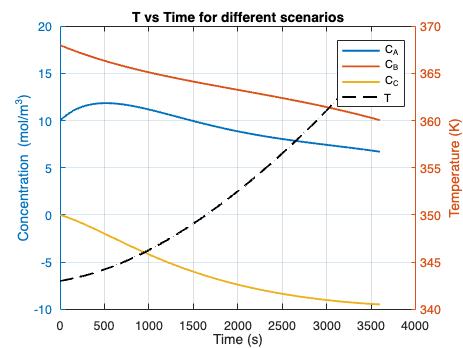

[X, Y] = solveEquationSystem(paramsFinal);


figure;

yyaxis left
plot(X, Y(:,1), '-', 'LineWidth', 1.5, 'Color', [0 0.4470 0.7410]); 
hold on;
plot(X, Y(:,2), '-', 'LineWidth', 1.5, 'Color', [0.8500 0.3250 0.0980]);
plot(X, Y(:,3), '-', 'LineWidth', 1.5, 'Color', [0.9290 0.6940 0.1250]); 
xlabel('Time (s)');
ylabel('Concentration (mol/m^3)');

yyaxis right
plot(X, Y(:,4), 'k--', 'LineWidth', 1.5);
ylabel('Temperature (K)');

title([vars{k} ' vs Time for different scenarios']);
legend({'C_A', 'C_B', 'C_C', 'T'}, 'Location', 'best');
grid on;